
close all;
clear all;
colors=npg(10); % Ten basic colors


## 理论计算


kB = Constant.Boltzmann;
T = 4e-3*3/4;   % 电流12A，AM 1.1V 阱深
U0 = kB*T;   % Lattice
V0 = U0/4;   % ODT
lambda = 1036e-9;
M = 0.171/Constant.AvogadroNumber;   % 原子质量
w0 = 20e-6;   % 束腰半径

freq_a1 = sqrt(2*U0*1/(M*lambda^2))*1e-3;   % 轴向 kHz

freq_a2 = sqrt(pi^2*32*V0/(M*lambda^2))/(2*pi*1e3);   % 轴向 kHz
freq_r2 = sqrt(16*V0/M)/(w0*2*pi*1e3);   % 径向 kHz


## 数据处理


RF = -0.3;   % dBm
AM_freq = [0.1 0.12 0.16 0.2 0.25 0.3 0.4 0.5 0.6 0.8 1 1.2 1.5 2 2.5 3 4 5 6 8 10 12 16 20 25 30 40 50];   % kHz

file_list = [172:10:442];   % last files

for k = 1:length(file_list)

    maindir=['\\Artemis-pc\e\Data\2024-01-03\Abs-',num2str(file_list(k)),'\'];
    main_dir=maindir;
    load([maindir,'\population.mat']);

    n_atom(k) = mean(n1);
    std_atom(k) = std(n1);

end


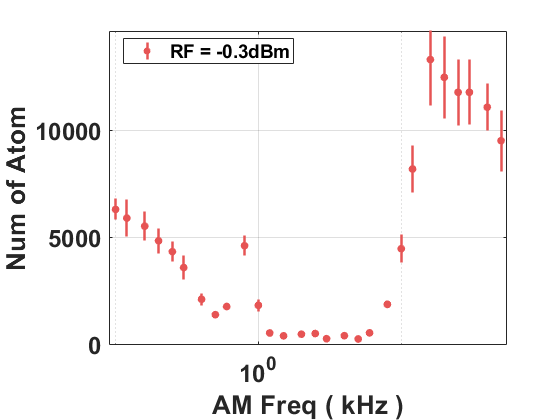


h1 = figure;
I1 = errorbar(AM_freq,n_atom,std_atom,'.','Color',[0.9 0.33 0.33],...
    'MarkerSize',20,'CapSize',0,'LineWidth',1.8);

xlim([min(AM_freq)*0.9 max(AM_freq)*1.1]);
ylim([0 max(n_atom)*1.1]);

xlabel('AM Freq ( kHz )');
ylabel('Num of Atoms');
%title('Trap Frequency','FontName','Arial','FontWeight','bold');
legend(['RF = ',num2str(RF),'dBm'],'Location','best','FontSize',14);

grid on;
set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
    'XScale','log','YScale','linear');
set(gcf,'Visible','on');

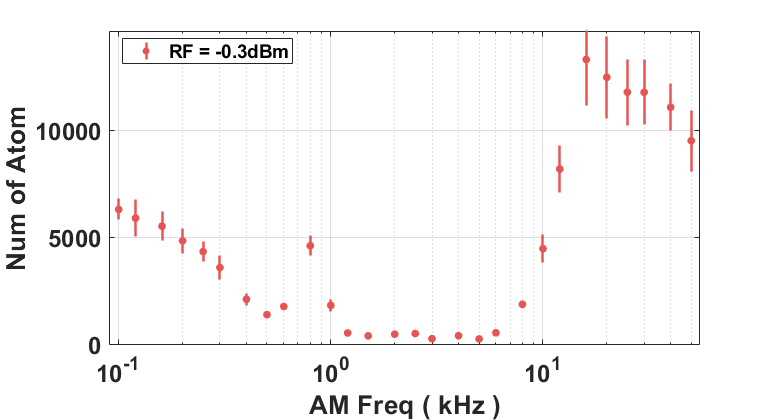


savefig(h1,[main_dir,'trap_freq.fig']);
saveas(h1,[main_dir,'trap_freq.png']);


save([main_dir,'\trap_freq.mat']);